# Vehicle Motion Planning and Control

The main vehicle motion planning and control block diagram is shown below. For the vehicles using the Stanley Lateral Controller, the Local Trajectory Planner doesn't output the coordinates of the next waypoints but the pose and the orientation of the closest waypoint on the path that is perpendicular to the front axle of the vehicle. The output of the Stanley Lateral Control is the steering angle command, which is same as the Pure Pursuit Lateral Controller. Therefore the superclass `Local Trajector Planner` is shown below but in the implementation the subclass `Stanley_RefPoseGenerator.m` or `PurePursuit_WPGenerator.m` is used.

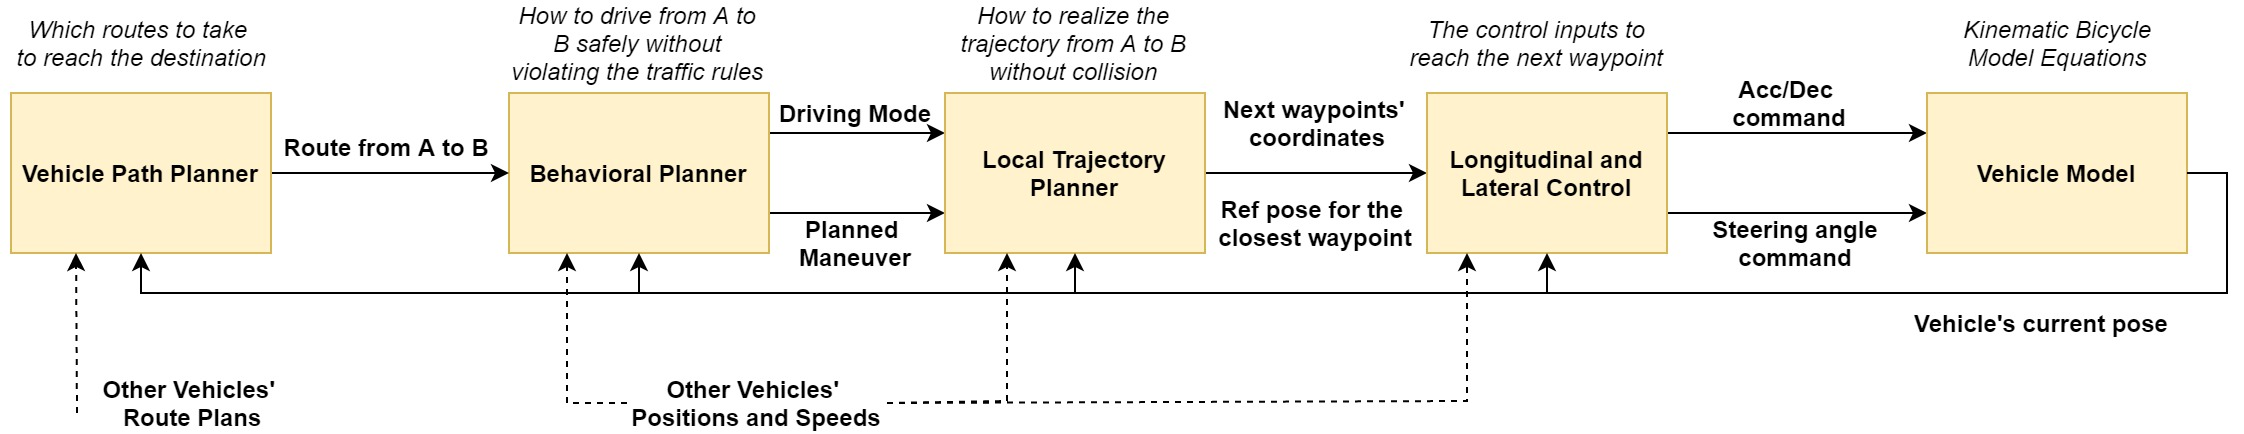

This figure illustrates the motion planning for the vehicle from the highest level on the left until the vehicle model. Note that it doesn't show the V2V Data influx coming to the Vehicle Path Planner or the Sensors Block output. The structure in MOBATSim therefore, is not exactly the same but this abstraction defines how an autonomous vehicle in MOBATSim reaches the destination node from the starting node. One of the ideas behind MOBATSim's development is the modularity and decoupling between components. So the motion planning explained in this document is still valid even when other vehicles come into play. The protocols for interactions with other vehicles, mechanisms to cope with their unexpected behavior,  and their actions shall be explained in another chapter.

# Vehicle Path Planner

The abstract superclass **Vehicle Path Planner** has two subclasses for implementation. `VehiclePathPlanner_shortestPathFinder.m `takes the digraph structure of the map as an input and outputs the shortest path based on the length of the edges between nodes. It doesn't take the other vehicles and their planned paths into account, therefore, it always outputs the shortest possible path based solely on the sum of the distance.

The `VehiclePathPlanner_Astar.m` subclass is more commonly used and it takes an extra input which is the shared data by other autonomous vehicles. At the beginning of the simulation, all the vehicles make a path plan based on a set of nodes and edges. In this plan, they also calculate their estimated time of arrival to each waypoint. When vehicles make the whole plan, which is a discrete set of waypoints to be visited in order to reach the destination waypoint, they also share it with other vehicles if they have the V2V connection. This enables the replanning of the path for some of the vehicles in certain circumstances, such as, if there is a short path which is occupied by a slower vehicle and a longer path that has faster vehicles on it, depending of the estimated time of arrival, the vehicle can replan its path and choose the longer but faster route. This reduces the traffic congestion if faster vehicles can avoid following slower vehicles on single lane roads.

The code snippet above can be seen in the superclass with the set of abstract methods that are defined. These abstract methods have to be implemented by any subclass, as it requires some common procedures to ensure compatibility.

# Behavioral Planner

At the moment there are two separate files for the Behavioral Planners. One of them is used for most of the vehicles and it has the name `VehicleDrivingMode.m`. The second vehicle has the lane-changing maneuver implemented, so it has a few different functions and it is only implemented in Vehicle 2 at the moment (`VehicleDrivingMode_Ego.m`).

# Local Trajectory Planner

The local trajectory planner is the superclass of two classes. This section covers mostly the theory and the implementation of the superclass functions. The details and differences between Lateral Stanley Controller and Pure Pursuit are mentioned briefly.

## Frenet Coordinate System

Frenet coordinate system is a coordinate system that is relevant to the road specifications that the vehicle is currently traversing. It is uses the road structure that MOBATSim is based on, which consists of straight and curved roads. At each road segment, which is referred to as **route** in MOBATSim, the vehicle starts from the s=0 coordinate and then moves to the s=s_endPoint. The curved road also uses the angles around the rotation point of the curve, as each arc has a constant curvature. 

One of the most important uses for the Frenet Coordinate System is that allows the vehicles to define some of the lateral maneuvers such as the lane-changing and overtaking maneuvers regardless of the road structure. Rather than creating separate functions for straight and curved roads according to their position on the global x-y coordinate system, the maneuvers are going to be defined in the Frenet Frame. However, how these maneuvers are defined will be explained after the transformations.

In this section the coordinate transformations from the global cartesian system to the Frenet Frame and then back to Cartesian Coordinates to create required output for the lateral controllers will be explained. So let's start with the straight road.

### Straight Road - Cartesian to Frenet Coordinates

The longitudinal coordinate s starts from the starting point and goes to the end point of the route. On a single lane road shown below, the s value of the end point is the length of the vector. The reference for the road center line is always d=0 and any deviation to the left is positive d direction and the right-side is negative d direction. The car in the example figure is not exactly on the road and its orientation phi is also not the same as the road orientation theta. Therefore the vehicle tries to make its lateral displacement d value zero by steering left. The projection of the vehicle's position on the AB vector gives the traversed part of the line. This value is obtained by the dot product of the unit vector of AB and AV. In a similar fashion, the lateral displacement can be calculated by multiplying the vehicle's displacement vector with the normal vector of the road, which is always perpendicular to the unit vector of AB and points left.

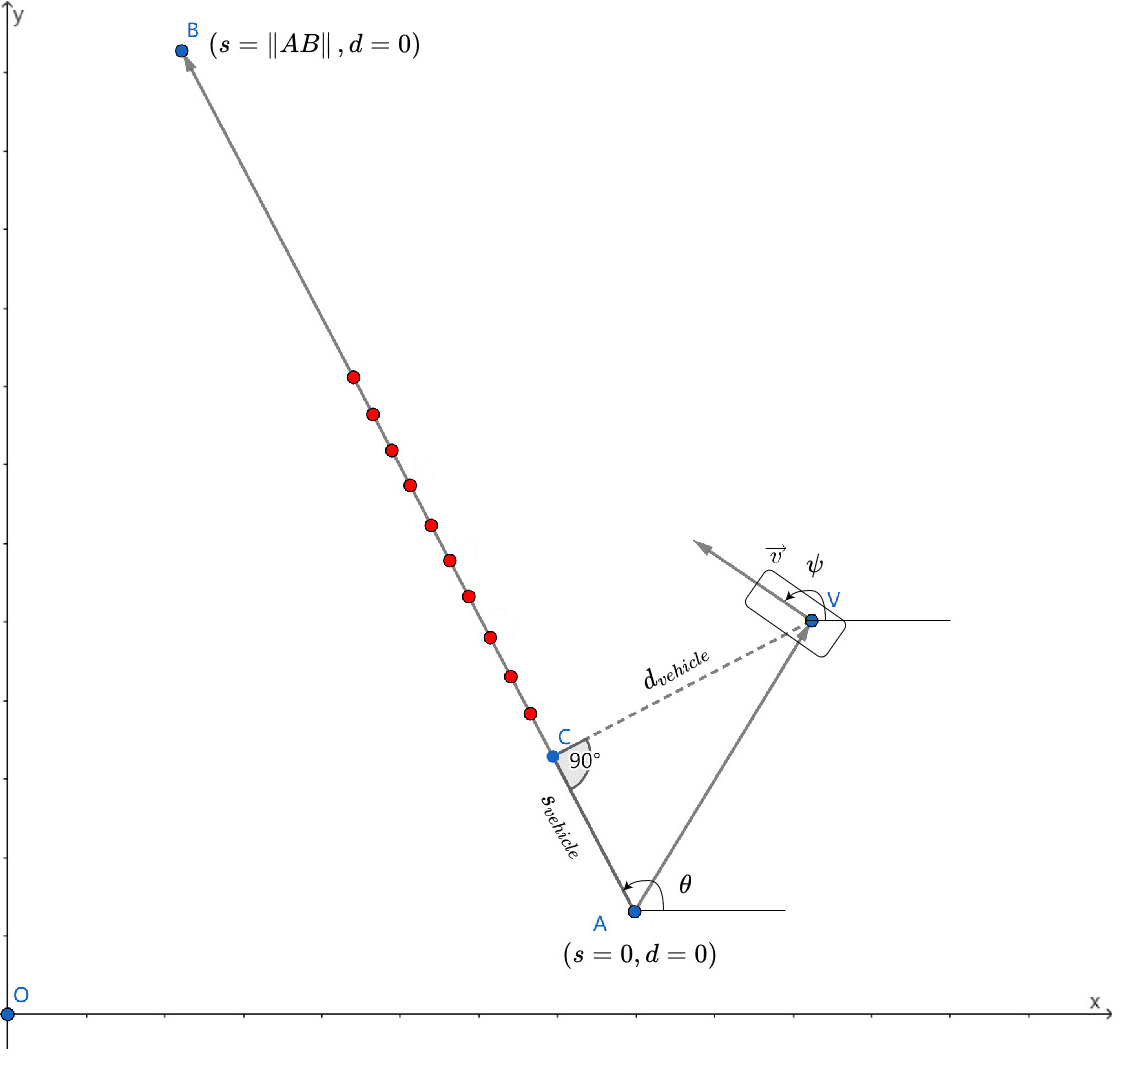

where,


$$A:\textrm{Starting}\;\textrm{point}\;\textrm{of}\;\textrm{the}\;\textrm{current}\;\textrm{route}\;\left(s=0\right)$$



$$B:\textrm{Destination}\;\textrm{point}\;\textrm{of}\;\textrm{the}\;\textrm{current}\;\textrm{route}\left(s=\left\|\textrm{AB}\right\|\right)$$



$$C:\textrm{Projection}\;\textrm{of}\;\textrm{the}\;\textrm{vehicle}\;\textrm{vector}\;\textrm{to}\;\textrm{the}\;\textrm{route}\;\left(\left\|\textrm{AC}\right\|=s_{\textrm{vehicle}} \;\textrm{and}\;\left\|\textrm{CV}\right\|=d_{\textrm{vehicle}} \right)$$


$\theta :\textrm{Orientation}\;\textrm{of}\;\textrm{the}\;\textrm{straight}\;\textrm{route}$ (angle from the $x$ axis)


$$V:{\textrm{Vehicle}}^{\prime } s\;\textrm{current}\;\textrm{position}$$



$$\overrightarrow{v} :\textrm{Velocity}\;\textrm{vector}\;\textrm{of}\;\textrm{the}\;\textrm{vehicle}$$


$\phi :\textrm{Orientation}\;\textrm{of}\;\textrm{the}\;\textrm{vehicle}$ (angle from the $x$ axis)

$O$: Origin of the global cartesian coordinate system $\left(x,y\right)$.

Here is another example below where the road is double lane. The right lane is always the d=0 reference and the left lane's d value is equal to 3.7 meters. This is the standard road geometry in MOBATSim, however it can be edited. In this example let's consider the road length to be 100 meters from A to B and then determine the values of the vehicles at the given state. Yellow vehicle is making a lane-changing manevuer by steering left, hence it is taking the left lane (d=3.7 line) as the reference. The purple vehicle is on the right lane and a little bit ahead, therefore it has a greater s value. The green vehicle is way ahead of the other vehicles, so it has the highest s value and also it is driving straight with d=3.7. Even though the green vehicle is also trying to reach the end of the road, here it suffices to reach s=100 with d=3.7 if the next road segment is also a double road. Hence, the waypoint reach trigger is not directly based on a point but an imaginary line that is perpendicular to the road flow direction and covers the d values other than d=0. 

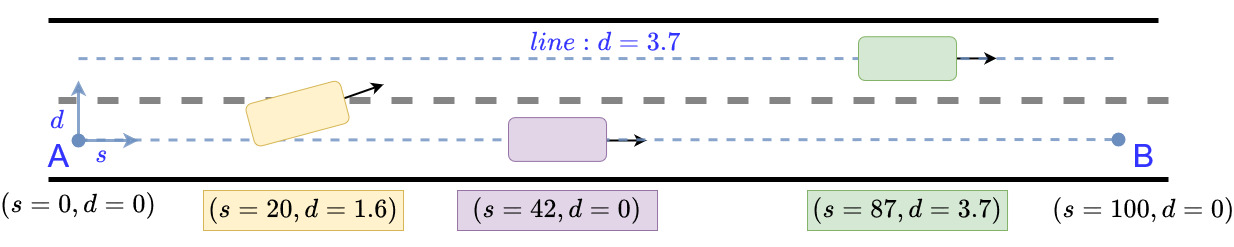

Here is a code snippet for calculating the s and d values on a straight road.

### Straight Road - Frenet to Cartesian

After the vehicle localizes itself according to the Frenet Frame, it will plan its next intermediate waypoint to visit. If the vehicle is going on the right lane, doesn't matter if it is a straight road or a curved road, it will be traveling along the $s\;\textrm{axis}\;$with a lateral displacement of $d=0$. So the next point should be $\acute{s} =s+\Delta s$ with also $d=0$. As the lateral controllers give commands in the Cartesian Coordinate System (this might be updated in the future to work also according to vehicle's frame) they need either the coordinates of the next waypoints for Pure Pursuit Lateral Controller or the reference pose for the Stanley Lateral Controller. The required outputs are calculated similarly by first calculating the route vector, its magnitude along the $s$ axis and by adding the starting point of the route as everything is relative to the route but we need the global coordinates. Here there is also an extra output required by the Stanley Controller which is the reference orientation of the point. As this point lies on the route which is a straight line, it can easily be calculated by the atan2d function in degrees, as the Lateral Stanley Controller Block in MATLAB requires this input in degrees.

### Curved Road - Cartesian to Frenet Coordinates

Curved roads are based on arcs which have a constant radius (thereby a constant curvature) along an angle that sweeps from the starting point to the end point of the route segment. In the figure below, you can see three road segments with different radii, sweeping angles, and rotation centers. Further updates involving support for Bezier curves and other structures are planned but at the moment they are approximated by a number of arcs sequentially. The Frenet coordinate system for arcs also follow the same coordinates, namely "s" and "d" but the calculation is not as straightforward as the in the straight road segments.

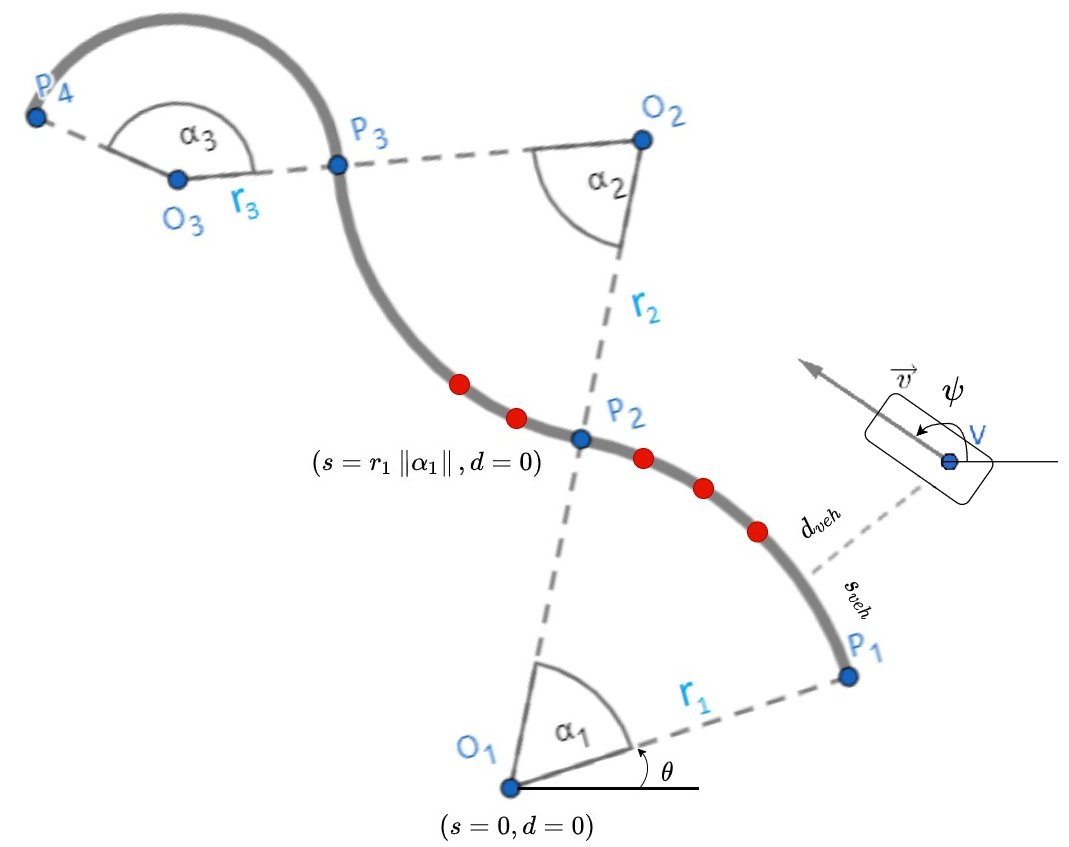

The length of an arc is given by:  $s_i =r_i \;\alpha_i$ where $r_i$ is the radius of the road segment i and $\alpha_i$ the sweeping angle in radians. Therefore it is imperative to calculate the vehicle's position according to the rotation center O to be able determine the projection of vehicle's traversion over the arc. Note that the road segment "s" values change relatively. For the road segment 1, the "s" value of point P2 is a positive definite number, whereas for road segment 2, since it starts with point P2, the value is equal to s=0. These discrete jumps are via checkWaypointReached functions with an $\epsilon$ tolerance value.

The two code snippets shown above are actually combined into one function called Cartesian2Frenet and an if statement separates the straight road from the curved one according to the radian value, which is zero for straight roads.

### Curved Road - Frenet to Cartesian Coordinates

## Lane-Changing Maneuver

### Minimum Jerk Trajectory Generation

### Using Pure Pursuit

### Using Lateral Stanley Controller

### Overtaking Maneuver

# ------------------------------------------

# A minimum jerk trajectory

This m function is the trajectory generator with a minimum jerk for vehicle lane-switching. The trajectory, along with the vehicle's other physical state,i.e., speed and acceleration should be calculated and output for vehicle control.

## Jerk

Smoothness can be quantified as a function of a jerk, which is the third time derivative of location. If the location of a vehicle is specified by variable $x(t)$, then the jerk is:


$$\dddot x(t)=\frac{d^3x(t)}{dt^3}$$


For comfort consideration, the sum of the squared jerk along the vehicle's trajectory should be minimized. The jerk cost is measured by:


$$H(x(t))=\frac{1}{2}\int _{t_i} ^{t_f} \dddot x(t)^2dt
$$


where $t_i
$ and $t_f$ are start and end time of the trajectory. The $\frac{1}{2}$ factor in the front makes the calculation come out prettier; otherwise, it has no special significance).

We assume that the vehicle remains the same velocity at the beginning and end of the trajectory, which means $\ddot x(t_i)=\ddot x(t_f)=0$

## Calculus of the variations.

The technique calculus of the variation resembles finding the minimum of the function. The variation is a function we can name $\eta(t)$. The variation has the special property that it smoothly goes away at the boundary conditions, i.e., at the beginning and end of the trajectory:


$$\eta(t_i)=\eta(t_f)=0
\\ \dot \eta(t_i)=\dot \eta(t_f)=0
\\ \ddot \eta(t_i)=\ddot \eta(t_f)=0$$


To minimize $H(x(t))$,we first replace $x(t)$by a variation $x(t) \mapsto x(t)+e\eta(t)$:


$$H(x+e\eta)=\frac{1}{2}\int^{t_f}_{t_i}(\dddot x +e\dddot\eta)^2dt
\\ \frac{dH(x+e\eta)}{e}=\int^{t_f}_{t_i}(\dddot x +e\dddot\eta)\dddot \eta dt
\\ \frac{dH(x+e\eta)}{e} \big| _{e=0} =\int^{t_f}_{t_i}\dddot x \dddot\eta dt
$$


Using integration by parts, we can rewrite this integral as:


$$\int ^{t_f}_{t_i}\dddot x \dddot \eta dt=  \dddot x \dddot \eta \big| ^{t_f}_{t_i} -\int^{t_f}_{t_i} \ddot \eta x^{(4)}dt=-\int ^{t_f}_{t_i} \ddot \eta x^{(4)}dt$$


Continuing the integration by parts:


$$\int ^{t_f}_{t_i} x^{(5)} \dot \eta dt=   x^{(5)} \eta \big| ^{t_f}_{t_i} -\int ^{t_f}_{t_i}  \eta x^{(6)}dt=-\int ^{t_f}_{t_i}  \eta x^{(6)}dt$$


The final integral:


$$\frac{dH(x+e\eta)}{e} \big |_{e=0}=-\int^{t_f}_{t_i}\eta x^{(6)}dt =0$$


The above property must hold true for any function $\eta(t)$, and therefore we have the fact that $x^{(6)}=0$, which means that function $x(t)$should have its sixth derivative equal to zero to have a minimum jerk function. $x(t)$has the general form of:


$$x(t)=a_0+a_1t+a_2t^2+a_3t^3+a_4t^4+a_5t^5$$


with derivatives:


$$\dot x(t)=a_1+2a_2t+3a_3t^2+4a_4t^3+5a_5t^4
\\ \ddot x(t)=2a_2+6a_3t+12a_4t^2+20a_5t^3$$


## Implementation in Matlab

To find the constants of the function $x(t)$, boundary values are required as inputs of the m function:

frequency = 10;%Number of commands per sec
current_point=[10 10];%current_point is a 1x2 array that represents vehicle's location at the
%beginning of the lane-switching trajectory
t=3;% the time required for the whole trajectory
v_x=20;%the vehicle's x-direction speed at the beginning of the lane-switching
lane_width=5;%the distance between adjacent lane centerline 

%temperory variables for better understanding
x_i=current_point(1,1);
y_i=current_point(1,2);
x_f=t*v_x+x_i;
y_f=y_i+lane_width;

To calculate the 2-D trajectory, we use x and y to denote distance in longitudinal and lateral direction to vehicle framework:

We assume that the vehicle remains its velocity in x direction, thus we have:

x=[];
x_dot=[];
x_ddot=[];
for i=0:1/frequency:t
x=[x,i*v_x+x_i];
x_dot=[x_dot,v_x];
x_ddot=[x_ddot,0];
end
state_x=[x;x_dot;x_ddot];


$$y(t_i=0)=y_i \rightarrow a_0=y_i
\\ \dot y(t_i=0)=0 \rightarrow a_1=0
\\ \ddot y(t_i=0)=0 \rightarrow a_2=0;$$



$$y(t_f=t)=y_f \rightarrow a_3t^3+a_4t^4+a_5t^5=y_f
\\ \dot y(t_f=t)=0 \rightarrow 3a_3t^2+4a_4t^3+5a_5t^4=0
\\ \ddot y(t_f=0)=0 \rightarrow 6a_3t+12a_4t^2+20a_5t^3=0;$$


$a_3,a_4 $ and $a_5$ can be acquired by solving the equations above:

a0=y_i;
a1=0;
a2=0;
syms a3 a4 a5;
[a3,a4,a5]=solve([a0+a3*t^3+a4*t^4+a5*t^5==y_f,
3*a3*t^2+4*a4*t^3+5*a5*t^4==0,
6*a3*t+12*a4*t^2+20*a5*t^3==0,],[a3,a4,a5]);
a3=double(a3);
a4=double(a4);
a5=double(a5);

Thus the function of the most smoothly trajectory in y direction is arrived:

y=[];
y_dot=[];
y_ddot=[];
for i=0:1/frequency:t
y=[y,a0+a1*i+a2*i^2+a3*i^3+a4*i^4+a5*i^5];
y_dot=[y_dot,a1+2*a2*i+3*a3*i^2+4*a4*i^3+5*a5*i^4];
y_ddot=[y_ddot,2*a2+6*a3*i+12*a4*i^2+20*a5*i^3];
end
state_y=[y;y_dot;y_ddot];

Corresponding yaw angle is the arc tangent function `atan()` of $v_y/v_x$

yaw_angle=[];
for i=2:length(x_dot)
    yaw_angle(i)=atan(y_dot(i)/ (x_dot(i)));
end

We can then visualize the trajectory by using plot function:

figure
i=0:1/frequency:t;
subplot(4,1,1);
plot(state_x(1,:),state_y(1,:));
% pbaspect([2 1 1]);
legend('pos');
title("Minimum jerk trajectory");
xlabel("x direction[m]");
ylabel("y direction[m]");
subplot(4,1,2);
plot(i,state_x(2,:))
hold on;
plot(i, state_y(2,:));
legend('v_x','v_y');
title("Velocity");
xlabel("time[s]");
ylabel("Velocity[m/s]");
subplot(4,1,3);
plot(i, state_x(3,:));
hold on;
plot(i, state_y(3,:));
legend('a_x','a_y');
title("Acceleration");
xlabel("time[s]");
ylabel("acceleration[m/s^2]");
subplot(4,1,4);
plot(i, yaw_angle);
hold on;
plot(i, yaw_angle);
legend('yaw angle');
title("yaw angle");
xlabel("time[s]");
ylabel("yaw angle[rad]");



## Reference

Kyriakopoulos, K. J., & Saridis, G. N. (1991). Minimum jerk trajectory planning for robotic manipulators. *Cooperative Intelligent Robotics in Space*, *1387*, 159. https://doi.org/10.1117/12.25421

# Frenet and Cartesian Coordinate

As the figure shows, a curved road can be separated into several road segments with different start-endpoints and radians. With the position of start-endpoints and radian available, the whole road segment can be well determined. And to simplify the calculation process, a Frenet coordinate can be established for this road segment. 

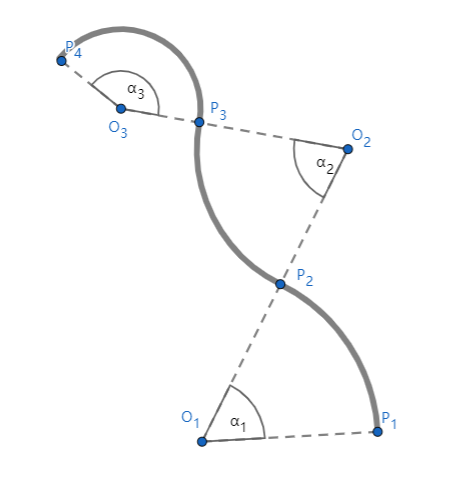

This file will explain how to establish a Frenet coordinate and transform positions between Frenet and Cartesian coordinates.

## Cartesian to Frenet

Function 'Cartesian2Frenet' transform a position in Cartesian coordinate into Frenet coordinate:

function [s,d,orientation_C] = Cartesian2Frenet(obj,route,position_C,radian)

input:

1. `route` is a 2x2 array `[x_s y_s;x_e y_e]` that contains the start point and the endpoint of the road. Subscript `s` and `e` denote start- and endpoint.

2. `position_C` is the 1x2 array `[x y]` in Cartesian coordinate

3. `radian` is the radian of the whole curved road, is positive when counterclockwise turn

output:

1. `orientation_C` is the angle of the tangent vector on the reference road `line(d=0)`

2. `s` is the journey on the reference road line

3. `d` is the vertical offset distance to the reference road line, positive `d` means away from the center

As the figure shows, $P_1
$ is the start point, and $P_2$ is the endpoint of the road,$O$ is the rotation center of the road segment,$C$ is the origin of the cartesian coordinate,$V$ is the vehicle's location:

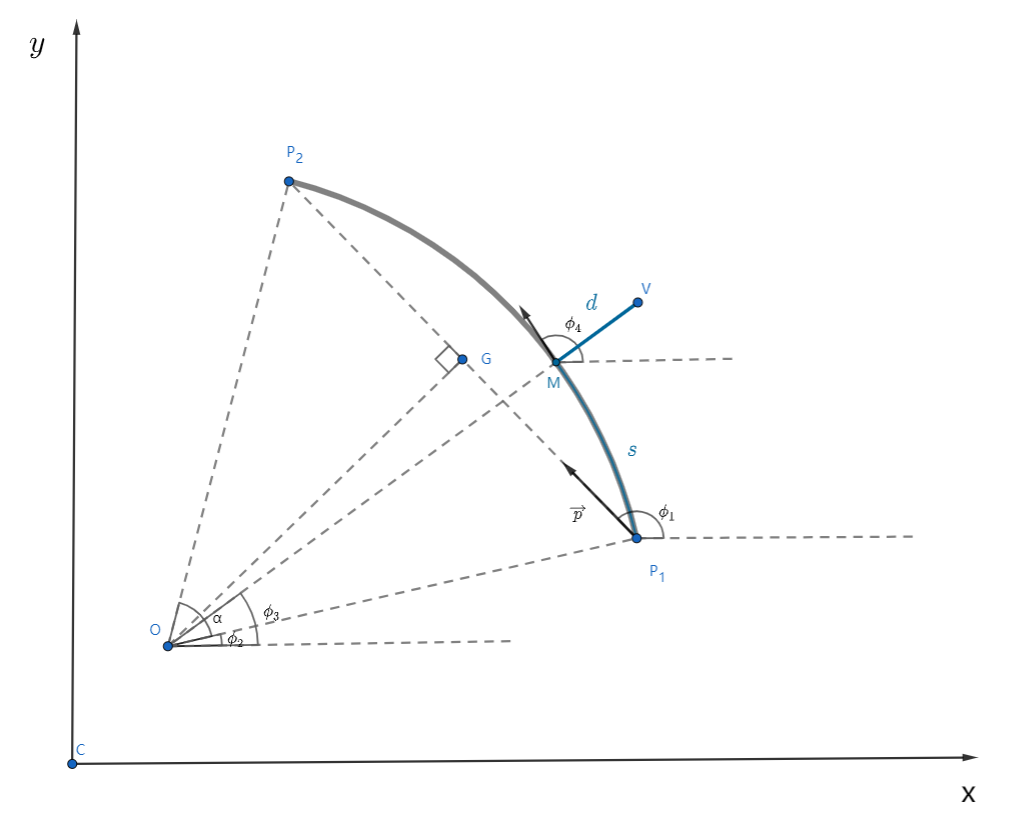

startPoint = route(1,:);
endPoint = route(2,:);

The radius of the road segment can be calculated according to the law of cosines:


$$|P_1P_2|^2=r^2+r^2-2r^2cos\alpha\\
r=\sqrt{\frac{|P_1P_2|^2}{2(1-cos\alpha)}}$$


r = sqrt((norm(endPoint-startPoint))^2/(1-cos(radian))/2);

$\phi_1$ is the angle of $\overrightarrow{P_1P_2}$'s unit vector $\overrightarrow p$ in cartesian coordinate.

targetVector = (endPoint-startPoint)/norm(endPoint-startPoint);
phi_1 = atan2(targetVector(2),targetVector(1));

The length of the plumb line of $P_1P_2$:


$$|OG| = r\cdot cos\frac{\alpha}{2}$$


plumbLength = cos(radian/2)*r;


$$ang(\overrightarrow{GO})=\theta=\phi_1+sign(\alpha)\cdot \frac{\pi}{2}$$


Here, a positive $\alpha
$ means the road rotates counterclockwise, a negative $\alpha
$ means clockwise.


$$\overrightarrow{GO} = (cos\theta \overrightarrow i +sin\theta \overrightarrow j) \cdot |OG|$$


$\overrightarrow i $ and $\overrightarrow j$ are unit vectors in cartesian coordinate.

plumbVector = [cos(phi_1+sign(radian)*pi/2) sin(phi_1+sign(radian)*pi/2)]*plumbLength;

The rotation center $O$ of the road segment:


$$\overrightarrow{CO} = \overrightarrow{CP_1}+\frac{1}{2}\overrightarrow{P_1P_2}+\overrightarrow{GO}$$


center = startPoint + targetVector*norm(endPoint-startPoint)/2 + plumbVector;

$\phi_2 = ang(\overrightarrow{OP_1})$:

startPointVector = startPoint-center;
startPointVectorAng = atan2(startPointVector(2),startPointVector(1));

To simplify the calculation later on, we need a $\phi_2$in $[0,2\pi)$:

startPointVectorAng2pi = mod(startPointVectorAng,2*pi);


$$\phi_3 = ang(\overrightarrow{OV})$$



$$d=|\overrightarrow{OV}|-r$$


l = position_C-center;
d = norm(l)-r;
lAng = atan2(l(2),l(1));
lAng2pi = mod(lAng,2*pi);


$$s = (\phi_3-\phi_2)\cdot r$$


s = sign(radian)*(lAng2pi-startPointVectorAng2pi)*r;

again, here multiply `sign(radian)` is to distinguish the situations that the road segment rotates counterclockwise or clockwise.

The angle of the tangent vector at crosspoint $M$


$$\phi_4 = \phi_3+\frac{\pi}{2}$$


orientation_C = lAng+sign(radian)*pi/2;
orientation_C = mod(orientation_C,2*pi);
orientation_C = orientation_C.*(0<=orientation_C & orientation_C <= pi) + (orientation_C - 2*pi).*(pi<orientation_C & orientation_C<2*2*pi);   % angle in (-pi,pi]

# Implementing vehicle dynamic model and waypoints generator algorithm into MOBATSim

This document introduces the vehicle dynamic model's implementation, along with the waypoints generator and pure pursuit controller into MOBATSim. This implementation aims to make MOBATSim more practical by enabling lateral movement control. The movement of a vehicle would be more realistic, and this gives MOBATSim more extendibility for further development.

function generate_straight_move_WPs(obj, car,Destination)

### Generate reference waypoints for straight move

Following figure shows how the reference waypoints for staight move are generated: 

The destination point $B
$ and route vector$\overrightarrow{AB}$ are transferred from MOBATSim coordinate into local coordinate.

local_route_Vector_i $\overrightarrow{ab}$ is the unit vector of $\overrightarrow{AB}$ in local coordinate.


$$\overrightarrow{ab}=\frac{\overrightarrow{AB}}{|\overrightarrow{AB}|}$$


local_destination = Destination.*[1 1 -1];
route_Vector = car.pathInfo.currentTrajectory(2,:)-car.pathInfo.currentTrajectory(1,:);
local_route_Vector_i = route_Vector/norm(route_Vector).*[1 1 -1];

pos_Vector $\overrightarrow{AV}$is from the route starting point to the vehicle's current position.

pos_Vector = car.dynamics.position-car.pathInfo.currentTrajectory(1,:);
local_pos_Vector = pos_Vector.*[1 1 -1];

setoff_distance $|\overrightarrow{AC}|$is the longitudinal traveled distance of the vehicle mapped to the current route.


$$|\overrightarrow{AC}|=\overrightarrow{AV}\cdot\overrightarrow{ab}$$


setoff_distance = dot(local_pos_Vector,local_route_Vector_i);

local_WP_start_point $C$ is the point where the reference waypoints start.


$$\overrightarrow{OC}=\overrightarrow{OA}+\overrightarrow{AC}$$


local_WP_start_point = (setoff_distance*local_route_Vector_i+car.pathInfo.currentTrajectory(1,:).*[1 1 -1]);

The next ten reference waypoints were generated with a step length $l_{step}=0.3\overrightarrow{v}\cdot\overrightarrow{ab}$. 


$$\overrightarrow{r_i}=\overrightarrow{OC}+i\cdot l_{step},    \qquad i =1,2,...10$$


To acoid instability of the controller, we allow the reference point to exceeds the destination point.

for i = 1:1:length(car.dynamics.reference_waypoints)
    car.dynamics.reference_waypoints(i,:) = local_WP_start_point+norm(i*(car.dynamics.speed*0.01*100))*local_route_Vector_i;
    %30 is the factor that adjust the reference WP step length
end

### Check if the vehicle has reached its destination.

After waypoints are generated, the moveto function will check if the vehicle has reached its destination to determine if another route should be taken.

To minimize the control error's influence and increase the system's redundancy, we consider the vehicle has reached its destination when the distance between the vehicle's current position and the destination point is smaller than 2 meters. 

if  norm(car.dynamics.position-Destination)<2
    %car.dynamics.position = Destination; %Because of the rounding errors may be modified later
    car.pathInfo.routeCompleted=true;
    car.pathInfo.lastWaypoint = car.map.get_waypoint_from_coordinates (Destination);

### generate waypoints for counterclockwise rotation

Like straight move, the moveto function will call up the `rotate_counterclockwise()` function when the vehicle's next movement is a left turn in its Freenet coordinate.

The user can add a breakpoint at line 169 to check the condition.

if car.pathInfo.currentTrajectory(4,:) == -ones(1,3) % -1 means turn counterclockwise
    obj.rotate_counterclockwise(car, rotation_point,rotation_angle,P_final);

The `rotate_counterclockwise()` function will call up the `generate_rotate_counterclockwise_WPs()` function to generate reference waypoints.

The user can add a breakpoint at line 347 to check the detailed algorithm.

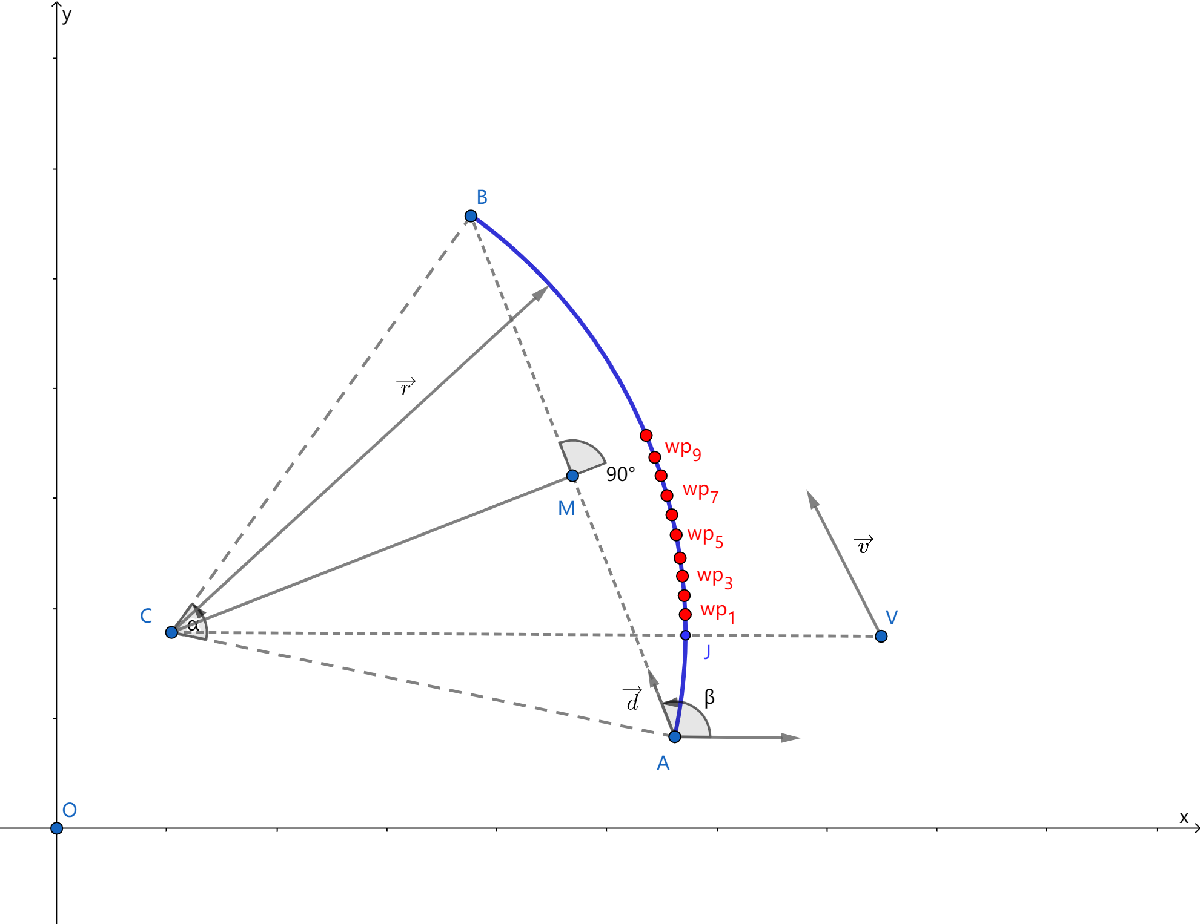

where,

$A$: the starting point for the current route

$B$: the destination point. 

$C$: Center of the rotation

$V$: Vehicle's current position

$O$: Coordinate origin

$M
$: the crosspoint of $AB
$ and its plumb line

$J$: the vehicle's position mapped to the current route

$wp_i
$: reference waypoints

$\overrightarrow{v}$: speed vector of the vehicle

Firstly, the vehicle position is transferred to the local coordinate.

local_position = car.dynamics.position.*[1 1 -1];

The sample time of the simulation is 0.01 seconds. Therefore step length $l_{step} = 0.01v$ 

step_length = car.dynamics.speed*0.01;

The rotation angle$\alpha$ and the start point of this whole route $A$ can be read from obj.Vehicle.

local_rotation_angle = car.pathInfo.currentTrajectory(3,1);
local_rotation_start_point = car.map.waypoints(obj.vehicle.pathInfo.lastWaypoint,:).*[1 1 -1];

The radius $r$ of the rotation:


$$|\overrightarrow{r}|=\sqrt{\frac{1}{2}\cdot\frac{|\overrightarrow{AB}|^2}{1-cos(\alpha)}}$$


r = sqrt((norm(Destination.*[1 1 -1]-local_rotation_start_point))^2/(1-cos(local_rotation_angle))/2);

corresponding to the step length, the step angle $\phi_{step}=\frac{l_{step}}{|\overrightarrow{r}|}$

step_angle = step_length/r; 

The local_displacement_vector $\overrightarrow{d}=\frac{\overrightarrow{AB}}{|\overrightarrow{AB}|}$ is the unit vector from the start point to the destination point.

local_displacement_vector = (Destination.*[1 1 -1]-local_rotation_start_point)/norm(Destination.*[1 1 -1]-local_rotation_start_point);

The `local_r_angle` $\beta
$ is the counterclockwise angle between x-axis and $\overrightarrow{d}$.


$$\beta =cos^{-1}(\overrightarrow{d}\cdot\overrightarrow{x_i})$$


local_r_angle = acos(dot(local_displacement_vector,[1 0 0]));

Mind that for real values of X in the interval [-1, 1], acos(X) returns values in the interval [0, π]. A check function was added to cover the case that $\overrightarrow{d}$ may lay in the third or fourth quadrants.

if (local_displacement_vector(3)<0)
    local_r_angle=2*pi-local_r_angle;
end

The plumb line $|\overrightarrow{AM}|=cos(\frac{\alpha}{2})\cdot|\overrightarrow{r}|$


$$\overrightarrow{AM}=|\overrightarrow{AM}|\cdot(cos(\beta+\frac{\pi}{2})\overrightarrow{x_i}+sin(\beta+\frac{\pi}{2})\overrightarrow{y_i})$$


local_plumb_length = cos(local_rotation_angle/2)*r;
local_plubm_vector = [cos(local_r_angle+pi/2) 0 sin(local_r_angle+pi/2)]*local_plumb_length;

The rotation center $C
$:


$$\overrightarrow{OC}=\overrightarrow{OA}+\frac{1}{2}\overrightarrow{AB}+\overrightarrow{MC}$$


local_rotation_center = local_rotation_start_point + local_displacement_vector*norm(Destination.*[1 1 -1]-local_rotation_start_point)/2 + local_plubm_vector;

Vehicle's relative position to the rotation center$\overrightarrow{l}=\overrightarrow{CV}$ 

l = local_position - local_rotation_center;

The next ten referecne waypoints were generated:


$$\overrightarrow{wp_i}_{polar}=|\overrightarrow{r}|\cdot\overrightarrow{r_i}+ang(\overrightarrow{CA})+ki\cdot\phi_{step} \qquad i=1,2,...10$$


where $wp_i$ is the Nr. i waypoints and $k$is the factor that can adjust waypoints length.

for i = 1:1:length(car.dynamics.reference_waypoints)
    target_point_P = [r,min(acos(dot(l,[1 0 0])/norm(l))+step_angle*(i-1)*30,local_rotation_angle+acos(dot(local_rotation_start_point-local_rotation_center,[1 0 0])/norm(local_rotation_start_point-local_rotation_center)))];
    target_point_C = local_rotation_center+[r*cos(target_point_P(2)) 0 r*sin(target_point_P(2))];
    car.dynamics.reference_waypoints(i,:) = target_point_C;
end

Here, P represents polar coordinate with rotation center $C$as coordinate origin and right as reference direction, C represents Cartesian coordinate with $O$.

### Check if the vehicle has reached its destination.

After waypoints are generated, the moveto function will check if the vehicle has reached its destination to determine if another route should be taken.

Similar to straight movement, we consider the vehicle has reached its destination when the distance between the vehicle's current position and the destination point is smaller than 4 meters. 

### Plot vehicle trajectory and referenc waypoints

The plot function from line 73 to 77 is only for debugging purpuse. It will slow down the simulation speed. Comment this out if it is not necessary.

figure(2)
WP = plot(reference_waypoints(:,1),reference_waypoints(:,2),'.','color','blue');
pos = plot(obj.vehicle.dynamics.position(1),-obj.vehicle.dynamics.position(3),'.','color','red');
xlim([obj.vehicle.dynamics.position(1)-200 obj.vehicle.dynamics.position(1)+200]);
ylim([-obj.vehicle.dynamics.position(3)-200 -obj.vehicle.dynamics.position(3)+200]);           
